## 1.MUA spike图

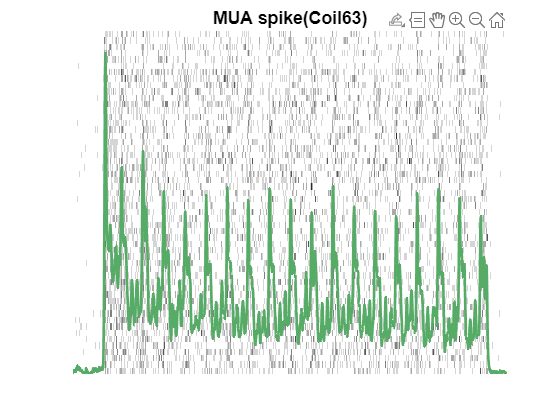

figure;
yyaxis left
data_spike =zeros(24,1640);
coilnum = 24;
load('D:\\Ensemble coding\\data\\SNR.mat','coilSNR');
[~,coilidx] = sort(coilSNR,'descend');
coilselect = coilidx(1:coilnum);


data_spike = -squeeze(SSVEP_data{6}(1:54,63,:));


imagesc(data_spike);
colormap("gray")
ylabel('trial')
ax =gca;
ax.YColor = [0,0,0];

yyaxis right
plot(smooth(squeeze(mean(data_spike,1))),'LineWidth',2.0,'Color',coilcolormap(170,:));
set(gca, 'YDir', 'reverse');

ax = gca;
ax.YColor = coilcolormap(170,:);
ylabel('Amplitude')
yticklabels({'1.4','1.2','1.0','0.8','0.6','0.4','0.2','0'});
title('MUA spike(Coil63)','FontSize',16,'FontWeight',"bold")
xlabel('Time')
xticklabels({'400','800','1200','1600','2000','2400','2800','3200'});
set(gca, 'FontSize', 12,'FontWeight','bold'); 
axis off;

## 2.Spike分布图

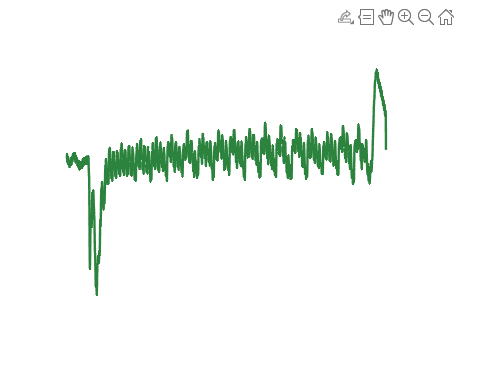

figure;
ori = (9+1)/2;
coil = 63;
% plot(squmean(k_fitting_data_random(:,coil,:),1),'LineWidth',2.0,'Color',[0.6,0.6,0.6]);
% hold on
% plot(squmean(k_fitting_data(:,coil,:),1),'LineWidth',2.0,'Color',[141,47,37]/256);

plot(squmean(SSVEP_data{ori}(:,coil,:),1),'LineWidth',2.0,'Color',[44,132,61]/256);

% xline(100,'--');

box off;
%xlim([0,1700]);
yticks([-300,0,300]);
xticks([500,1000,1500]);
xticklabels({'1000','2000','3000'});
% legend({'Random','Target90'},'Box','off');
ylabel('LFP(μF)')
xlabel('Time(ms)')
% text(150, 200, '200ms', ...
%         'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'left','FontWeight','bold');
ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';
axis off;